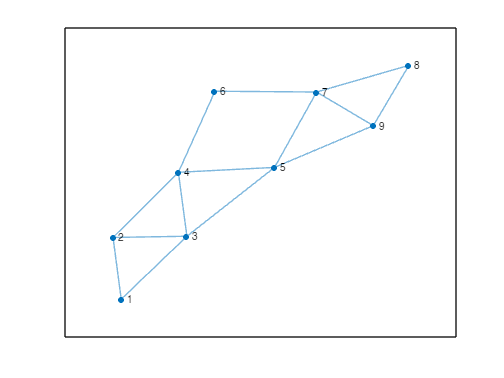

% 
clear all
clc
% global L
n = 9;
m = 14;
d = 3;
rng(5);

s = [1 1 2 2 3 3 4 4 5 5 6 7 7 8];
t = [2 3 3 4 4 5 5 6 7 9 7 8 9 9];
G = graph(s,t);
H = incidence(G)'*eye(9);
A12 = [1       sqrt(3)/2 0;
      sqrt(3)/2 1       0;
       0       0       0];
A13 = [0 0 0;
       0 1 0;
       0 0 1];
A23 = [2 1 0;
       1 1 0;
       0 0 1];
A24 = A13; A34 = A13;
A35 = [1 0 0;
       0 0 0;
       0 0 0];
A45 = diag([1, 2, 3]);
A78 = eye(3);
A79 = eye(3);
A89 = ones(3,3);
A46 = A89;
A67 = A12;
A57 = A35;
A59 = A13;
W = blkdiag(A12,A13,A23,A24,A34,A35,A45,A46,A57,A59,A67,A78,A79,A89);

Hbar = kron(H, eye(d));
L = Hbar'*W*Hbar;
[V,D] = eig(L, 'vector');
x0 = [];       % the agents are initially located on the unit sphere
for i = 1:9
    r = 2*(rand(3,1) - 0.5);
    x0 = [x0; r/norm(r)];
end

%G = graph(A);
plot(G)

 lambda = max(eig(L));
 tauMax = pi/(2*lambda)

tauMax = 0.1579

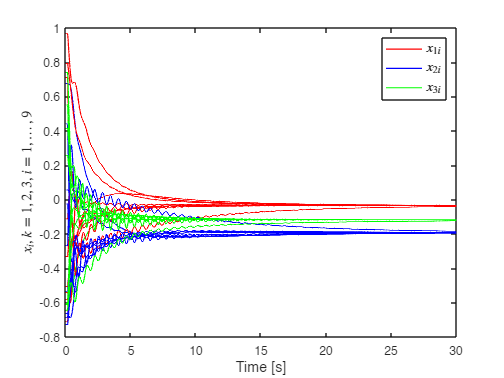

% Initialization
 t_end = 30;
% x0 = rand(d*n,1);
 tau = 0.15;
% Simulation with Simulink
 modelName = 'c12_ConsensusDelaysModel1';
 sim(modelName);

 t = ans.yout{1}.Values.Time;
 r = ans.yout{1}.Values.Data(:,1:d*n);
 
% Plot results
 figure
 hold on
 plot(t,r(:,1),"LineWidth",1,"Color",'r');
 plot(t,r(:,2),"LineWidth",1,"Color",'b');
 plot(t,r(:,3),"LineWidth",1,"Color",'g');
 plot(t,r(:,d+1:d:d*n),"LineWidth",1,"Color",'r');
 plot(t,r(:,d+2:d:d*n),"LineWidth",1,"Color",'b');
 plot(t,r(:,d+3:d:d*n),"LineWidth",1,"Color",'g');
 legend({'$x_{1i}$','$x_{2i}$','$x_{3i}$'}, "Interpreter", "latex", "FontSize", 12)
 xlabel('Time [s]', "FontSize", 12)
 ylabel('$x_i,~k=1,2,3,~i=1,\ldots,9$', "Interpreter", "latex", "FontSize", 12)
 box on

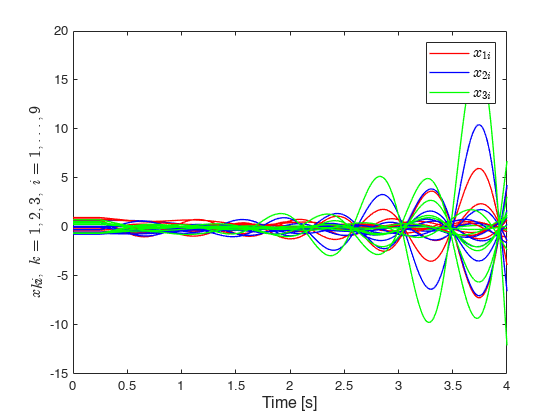

 % Simulation with Simulink
 % clear all
 t_end = 4;
 tau = 0.25;
 modelName = 'c12_ConsensusDelaysModel1';
 sim(modelName);
 t1 = ans.yout{1}.Values.Time;
 r1 = ans.yout{1}.Values.Data(:,1:d*n);
 
 % Biểu diễn hệ
 figure
 hold on
 plot(t1, r1(:,1), "LineWidth", 1, "Color", 'r');
 plot(t1, r1(:,2), "LineWidth", 1, "Color", 'b');
 plot(t1, r1(:,3), "LineWidth", 1, "Color", 'g');
 plot(t1, r1(:,d+1:d:d*n), "LineWidth", 1, "Color", 'r');
 plot(t1, r1(:,d+2:d:d*n), "LineWidth", 1, "Color", 'b');
 plot(t1, r1(:,d+3:d:d*n), "LineWidth", 1, "Color", 'g');
 legend({'$x_{1i}$','$x_{2i}$','$x_{3i}$'}, "Interpreter", "latex", "FontSize", 12)
 xlabel('Time [s]',"FontSize",12)
 ylabel('$x_{ki},~k=1,2,3,~i=1,\ldots,9$', "Interpreter", "latex", "FontSize", 12)
 box on